run('BASIC.m')

sys_discret =
 
  0.0076672 (z-0.7239) (z-0.8621)
  -------------------------------
  (z-1.109) (z-0.6048) (z-0.5835)
 
Sample time: 0.094282 seconds
Discrete-time zero/pole/gain model.



## generate Data

Question_mark='Q212';
[uc,t,Status,tfinal]=Datagen(0,T_s,1200);

Status = '_No NOISE_'

Titlework=[Question_mark,Status]

Titlework = 'Q212_No NOISE_'

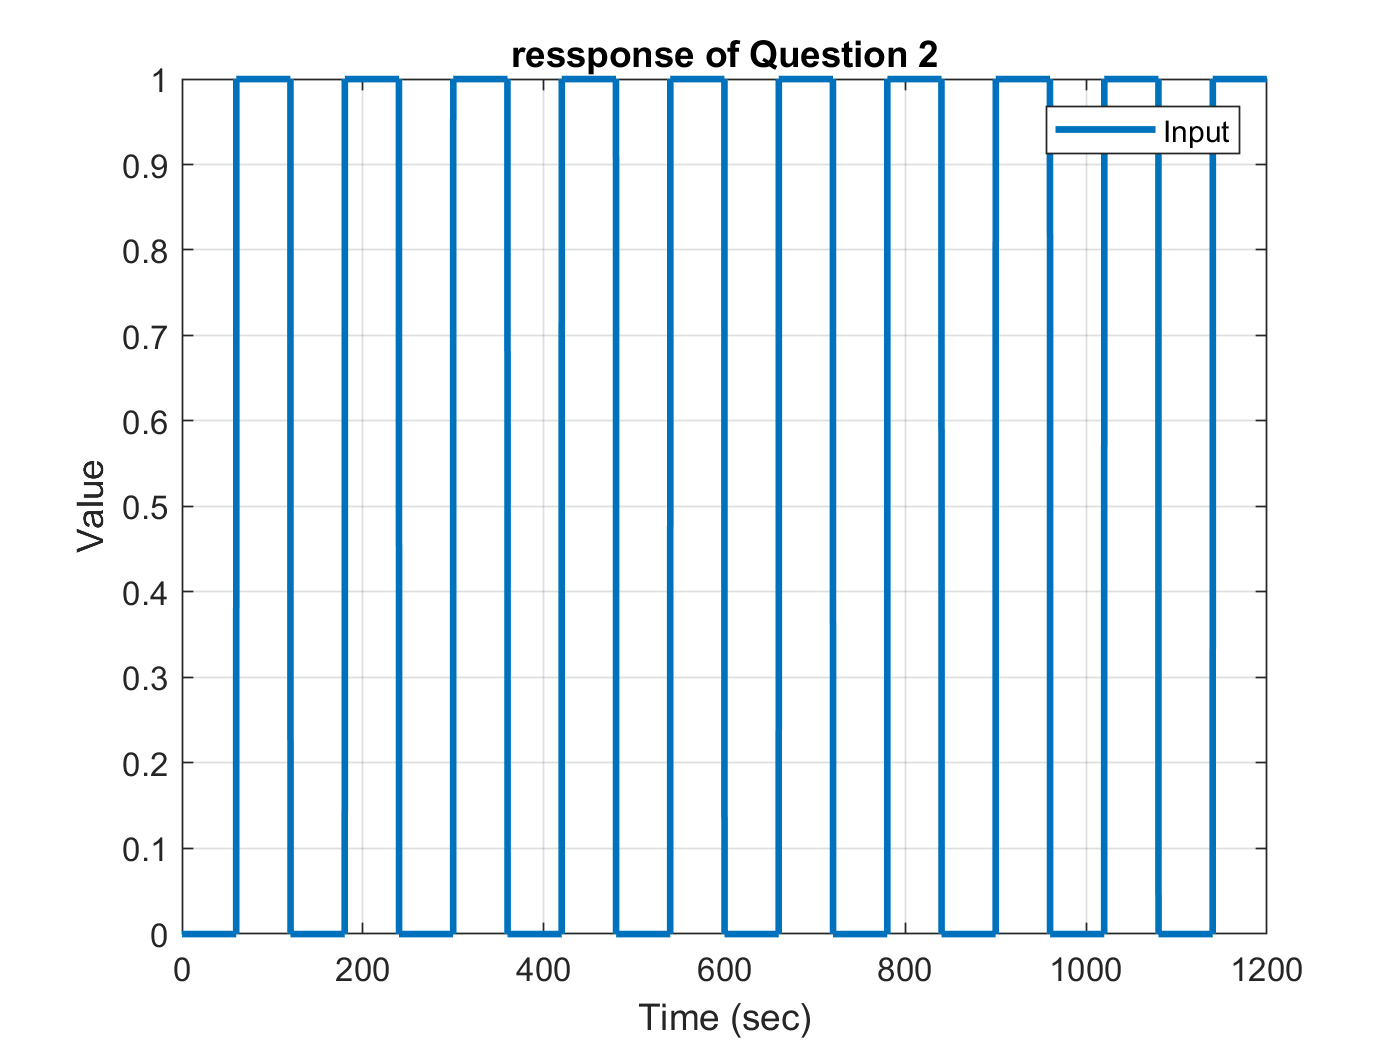

y = lsim(sys_discret  ,uc ,t);
plot(t,uc ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;
print(gcf,[Titlework , num2str(plot_counter) ' Refrence .png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Assumption

%choose number of parameters
Parameters_in_den=3

Parameters_in_den = 3

Parameters_in_num=3

Parameters_in_num = 3

A_m=poly([0.8 0.80 0.8]);
B_m=(sum(A_m)/sum(B))*B;
sys_ref=tf(B_m,A_m,T_s)

sys_ref =
 
  0.2101 z^2 - 0.3333 z + 0.1311
  ------------------------------
  z^3 - 2.4 z^2 + 1.92 z - 0.512
 
Sample time: 0.094282 seconds
Discrete-time transfer function.



y_ref_plant = lsim(sys_discret  ,uc ,t)';
y_ref       = lsim(sys_ref , uc , t) ;

deg_A=Parameters_in_num+1;
deg_B=Parameters_in_den  ;
B_m=[sum(A_m),zeros(1,(deg_A-deg_B)+1)];

A_o=[1 0 0];

d0 = deg_A-deg_B ;
A_c_prim=conv(A_m,A_o);
deg_A_c_prim=numel(A_c_prim)-1;
L = deg_A_c_prim-d0;

##     RLS

number_R=3

number_R = 3

number_S=number_R;
L = 2 ;
Nv =number_R*2 ;

N = numel(y) ;
%% initial parameters
A0 = [1 0 0];
n = numel(A)-1 ;
m = numel(B)-1 ;
d0 = n-m ;
A0Am = conv(A0 , A_m) ;
Na0am = numel(A0Am)-1 ;

theta_sys=1*ones(6,1);
teta = 10*ones(Nv,1);

u  = uc                 ;  % initial effort control
uf = uc                 ;  % initial filtered effort control
yf = 0.1*ones(100 , 1)  ;  % initial filtered output 
ucf= uc                 ;  % initial filtered command signal
P_cont = 1e12*eye(Nv);
P_sys  = 1e12*eye(6);
R=zeros(3,N);
S=zeros(3,N);

###         RLS System

for i = Nv+1:N
    if i<40
        y(i) =  -A(2:end)*y(i-1:-1:i-n)+B*(u(i-1:-1:i-n)) ;

        phi_sys = [(y(i-1:-1:i-3))' , (u(i-1:-1:i-3))']';
        [theta_sys,P_sys]=RLS(theta_sys,phi_sys,P_sys,6,y(i));
        Aest=[1 -theta_sys(1:3 ,end)'];
        Best=theta_sys(4:6,end)';
    else
        y(i) =  -Aest(2:end)*y(i-1:-1:i-(numel(Aest)-1))+Best*(u(i-1:-1:i-numel(Best))) ;

        Y = y(i);%-y_ref(i);
        phi_sys = [(y(i-1:-1:i-Parameters_in_num))' , (u(i-1:-1:i-Parameters_in_den))']';
        [theta_sys,P_sys]=RLS(theta_sys,phi_sys,P_sys,6,Y);
        Aest=[1 -theta_sys(1:3 ,end)'];
        Best=theta_sys(4:6,end)';

        phi = [uf(i-d0:-1:i-number_R)' , yf(i-d0:-1:i-number_S)']';
        [teta,P_cont]    =RLS(teta,phi,P_cont,Nv,Y);
        Rst = teta(1:Nv/2)'         ;
        Sst = teta(Nv/2 +1:Nv)'     ;
        R(1:Nv/2,i)=teta(1:Nv/2)    ;
        S(1:Nv/2,i)=teta(Nv/2 +1:Nv);
        t0=sum(A_m)/sum(Best)          ;

        u(i)   = (-Rst(2:end)*u(i-1:-1:i-(numel(Rst(2:end))))...
            +t0*uc(i)...
            -Sst*y(i:-1:i-(numel(Sst)-1)))/Rst(1) ;

        uf(i)  = -A0Am(2:end)* uf(i-1:-1:i-Na0am)    +Best*u(i:-1:i-numel(Best)+1)  ;
        yf(i)  = -A0Am(2:end)* yf(i-1:-1:i-Na0am)    +Best*y(i:-1:i-numel(Best)+1)  ;
        ucf(i) = -A0Am(2:end)*ucf(i-1:-1:i-Na0am)   +Best*uc(i:-1:i-numel(Best)+1)  ;
    end
end

General Input v.s. Output

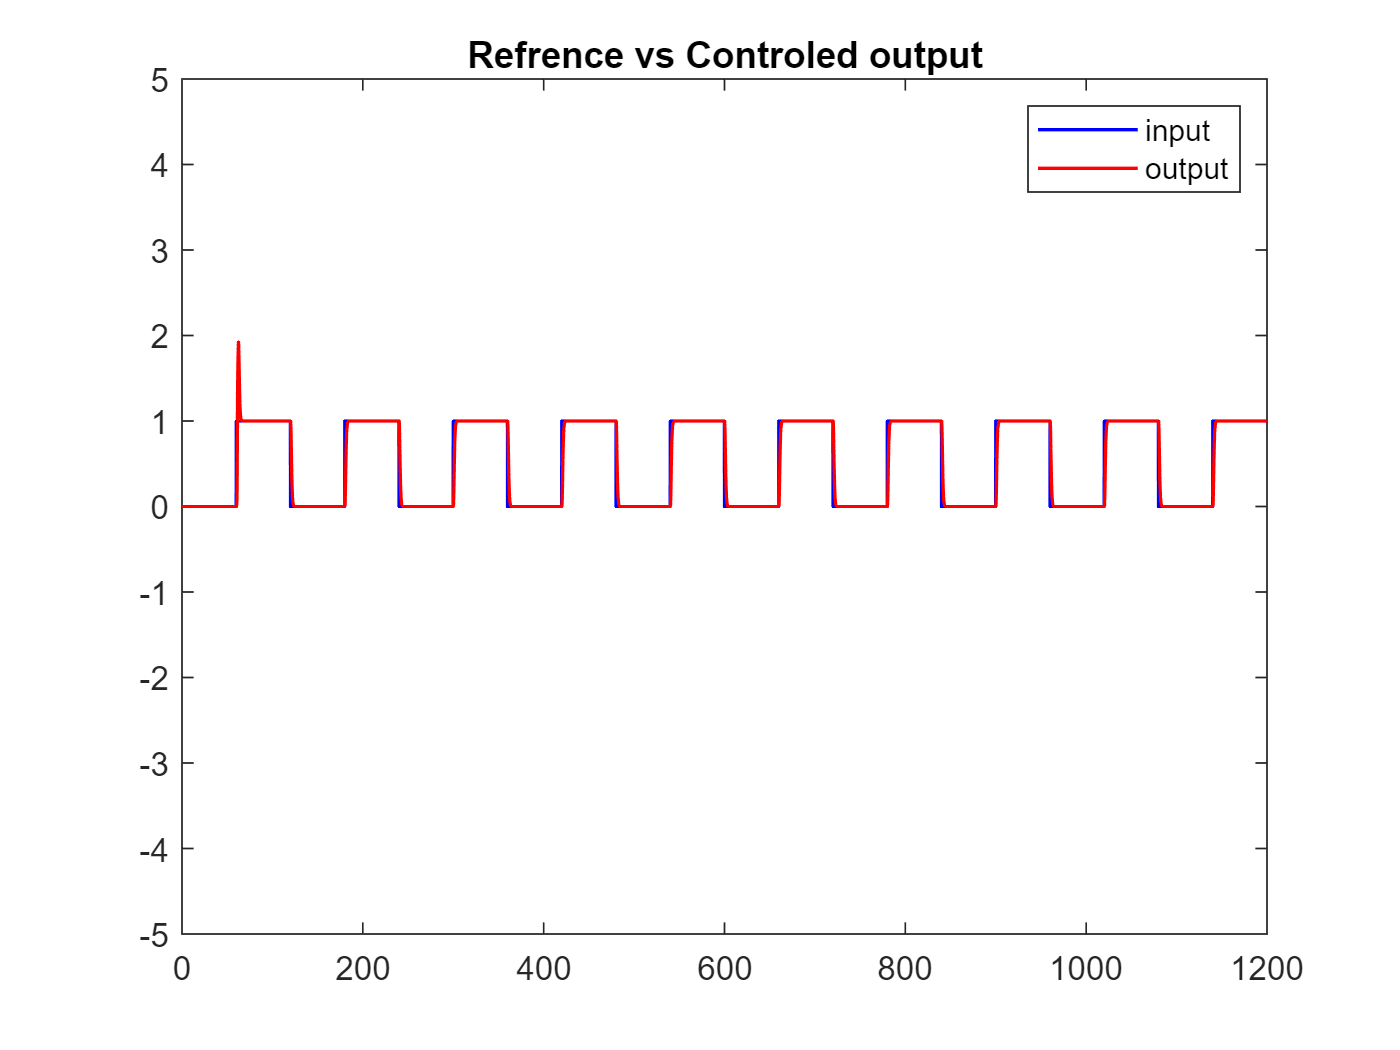

plot(t,uc,'b',t,y,'r','LineWidth',1)
title('Refrence vs Controled output')
legend('input','output')
xlim('auto')
ylim([-5 5])
print(gcf,[Titlework , num2str(plot_counter) ' Refrence vs Controled output.png'],'-dpng','-r400');

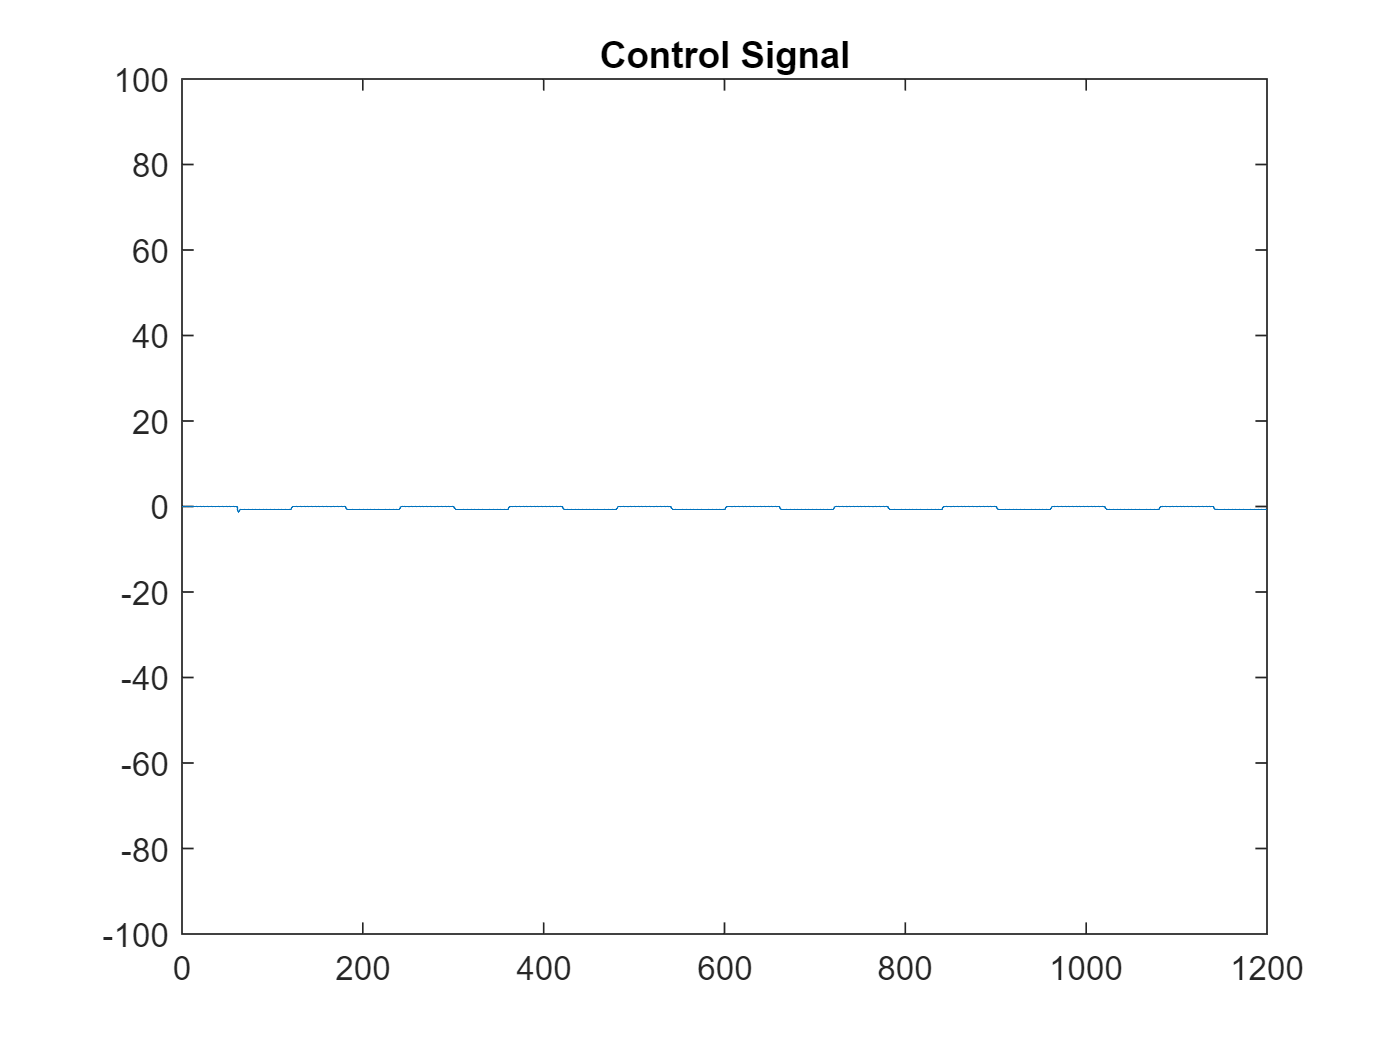

plot_counter=plot_counter+1;

plot(t,u)
title('Control Signal')
xlim('auto')
ylim([-100 100])
print(gcf,[Titlework , num2str(plot_counter) ' Control Signal.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

RLS Convergence of R UND S

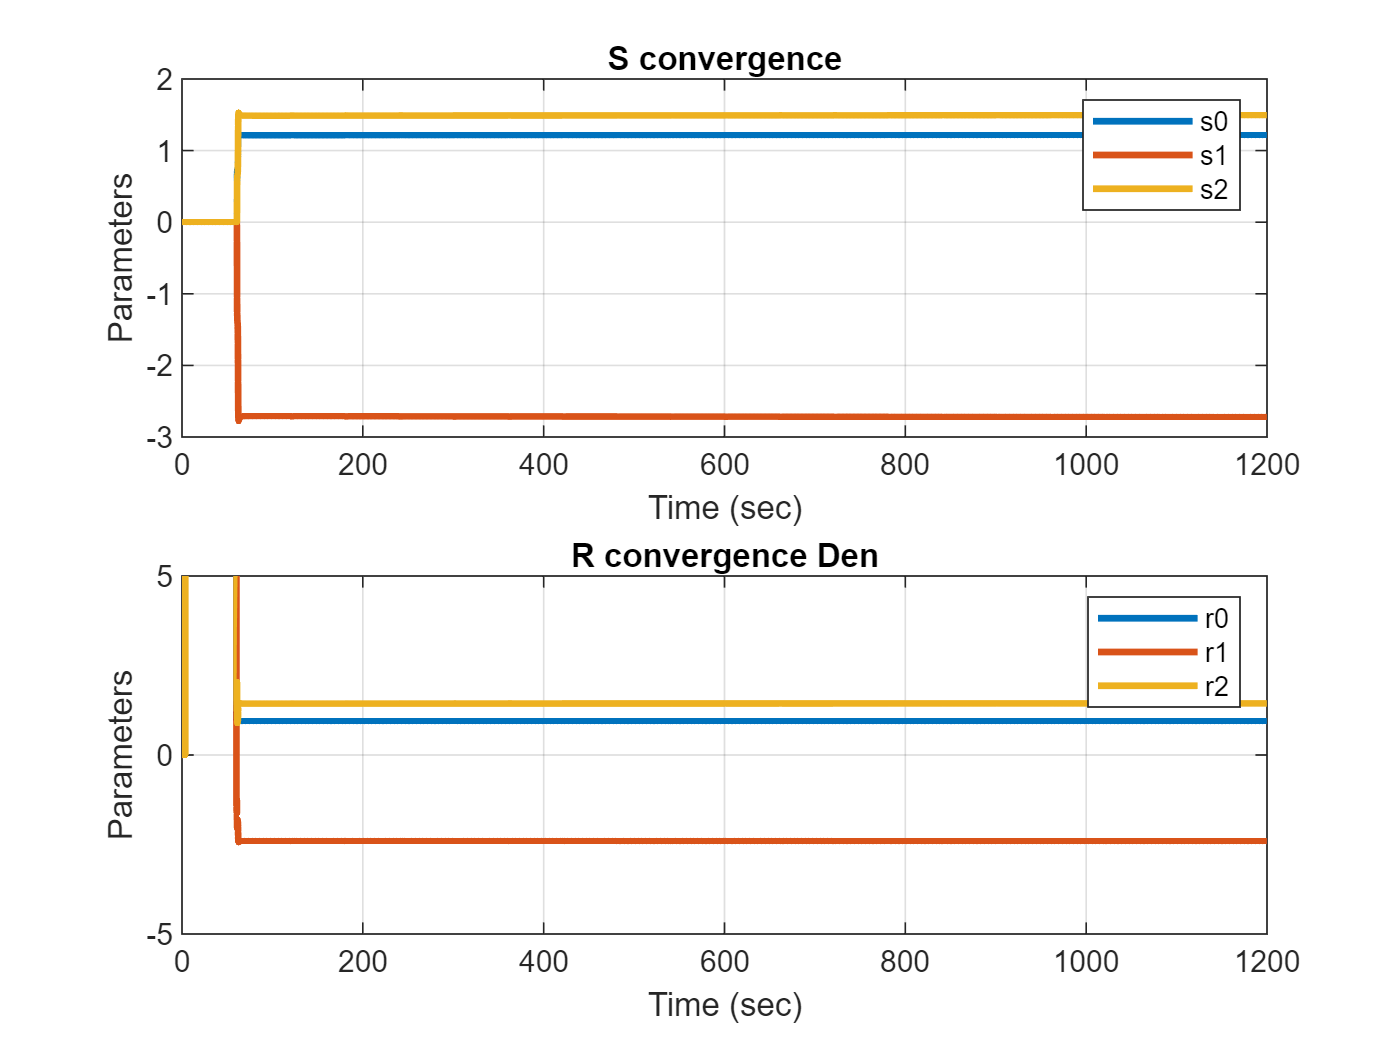

subplot(2,1,1)
for i=1:number_R
    legend_names{i} = ['s' num2str(i)-1 ''];
end
plot(t ,S(:,:), 'LineWidth' , 2) ;
legend(legend_names)
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('S convergence') ;
grid on


subplot(2,1,2)
for i=1:number_R
    legend_names{i} = ['r' num2str(i)-1 ''];
end
plot(t ,R(:,:), 'LineWidth' , 2) ;
legend(legend_names)
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('R convergence Den') ;
xlim('auto')
ylim([-5 5])
grid on
print(gcf,[Titlework , num2str(plot_counter) ' RLS Convegence.png'],'-dpng','-r400');

function [teta,P_sys]=RLS(teta,phi,P_sys,Nv,Y)
    K = P_sys*phi*(1+phi'*P_sys*phi)^(-1) ;
    P_sys = (eye(Nv) - K*phi')*P_sys ;
    teta = teta + K*(Y - phi'*teta ) ;
end